% 11-Sep-2018
%-------------------------------------------------------

%%
% Define images to process
clear
close all
clc

imageFileNames = {'D:\check_location\63.png',...
    'D:\check_location\98.png',...
    'D:\check_location\113.png',...
    'D:\check_location\143.png',...
    'D:\check_location\148.png',...
    'D:\check_location\188.png',...
    'D:\check_location\193.png',...
    'D:\check_location\223.png',...
    'D:\check_location\238.png',...
    'D:\check_location\268.png',...
    'D:\check_location\273.png',...
    'D:\check_location\313.png',...
    'D:\check_location\318.png',...
    'D:\check_location\348.png',...
    'D:\check_location\363.png',...
    'D:\check_location\393.png',...
    'D:\check_location\398.png',...
    'D:\check_location\438.png',...
    'D:\check_location\443.png',...
    'D:\check_location\473.png',...
    'D:\check_location\488.png',...
    'D:\check_location\518.png',...
    'D:\check_location\523.png',...
    'D:\check_location\563.png',...
    'D:\check_location\568.png',...
    'D:\check_location\598.png',...
    'D:\check_location\613.png',...
    'D:\check_location\648.png',...
    'D:\check_location\688.png',...
    'D:\check_location\723.png',...
    'D:\check_location\768.png',...
    'D:\check_location\813.png',...
    'D:\check_location\898.png',...
    'D:\check_location\938.png',...
    'D:\check_location\943.png',...
    'D:\check_location\973.png',...
    };

size(imageFileNames)

ans =      1    36



% Detect checkerboards in images
[imagePoints, boardSize, imagesUsed] = detectCheckerboardPoints(imageFileNames);

imageFileNames = imageFileNames(imagesUsed);
numImages = size(imageFileNames, 2)

numImages = 36

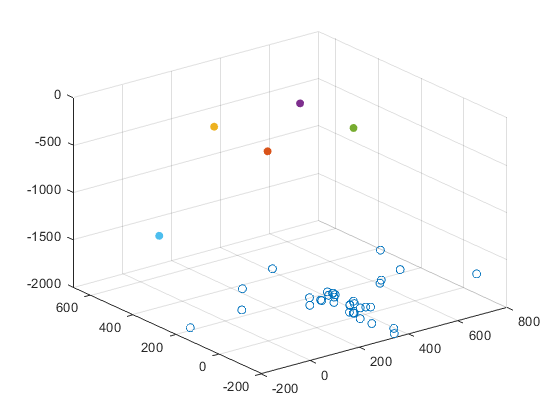


%%
% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates of the corners of the squares
squareSize = 50;  % in units of 'millimeters'
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

rotationVectors = zeros(3, numImages);
translationVectors = zeros(3, numImages); 

fx = 618.469482421875;
fy = 618.7632446289062;
skew = 0;
cx = 323.09356689453125;
cy = 237.54339599609375;

fx = 662.348631509985;
fy = 673.158030712524;
skew = 0;
cx = 349.358336125349;
cy = 238.979555744906;




A = [fx, skew, cx; ...
     0, fy, cy; ...
     0, 0, 1];

Ainv = inv(A);

for i = 1:numImages
    H = fitgeotrans(worldPoints, imagePoints(:,:,i), 'projective');
    H = (H.T)';
    H = H / H(3,3);
    
    h1 = H(:, 1);
    h2 = H(:, 2);
    h3 = H(:, 3);
    lambda = 1 / norm(Ainv * h1); %#ok
    
    % 3D rotation matrix
    r1 = lambda * Ainv * h1; %#ok
    r2 = lambda * Ainv * h2; %#ok
    r3 = cross(r1, r2);
    R = [r1,r2,r3];
    
    rotationVectors(:, i) = vision.internal.calibration.rodriguesMatrixToVector(R);
    
    % translation vector
    t = lambda * Ainv * h3;  %#ok
    translationVectors(:, i) = t;
end

rotationVectors = rotationVectors';
translationVectors = translationVectors';



figure
axis equal
t = -translationVectors;
scatter3(t(:,1),t(:,2),t(:,3))

hold on 
scatter3(0,0,0,'filled')
hold on 
scatter3(0,250,0,'filled')
hold on 
scatter3(350,250,0,'filled')
hold on 
scatter3(350,0,0,'filled')

hold on 
scatter3(151.3,680.5,-1705,'filled')